# Robust Stability for Unstructred Uncertainty

### 2.

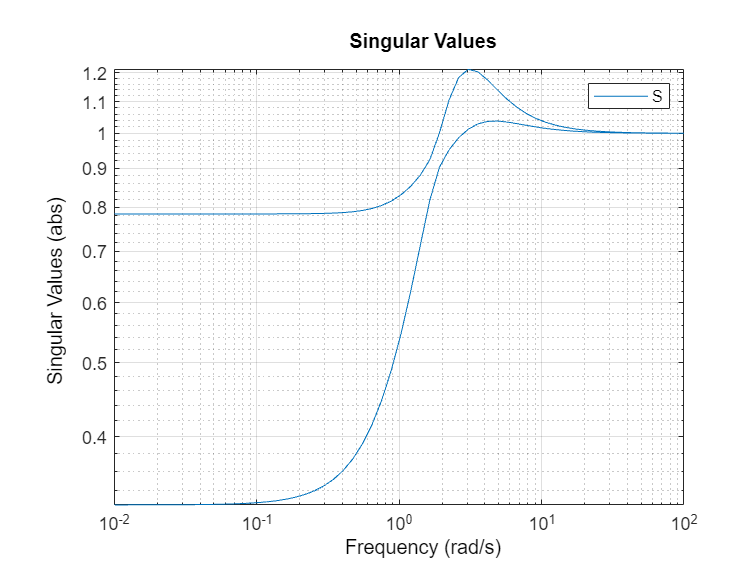

s = tf('s');
a = (s+1);
b = (s+2);
c = (s+3);
G = [2/a 1/(a*b);
     1/(a*b) 2/b];

K = [2/b 0;
     0 1/c];

L = K * G;
S = 1 / (eye(2) + L);
T = L * S;

figure
h = sigmaplot(S);
setoptions(h,'MagUnits','abs');
legend()

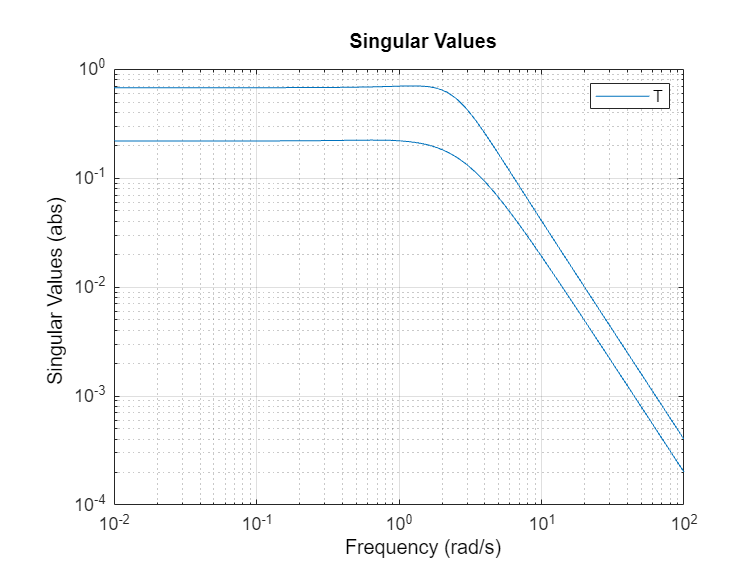


figure
h = sigmaplot(T);
setoptions(h,'MagUnits','abs');
legend()

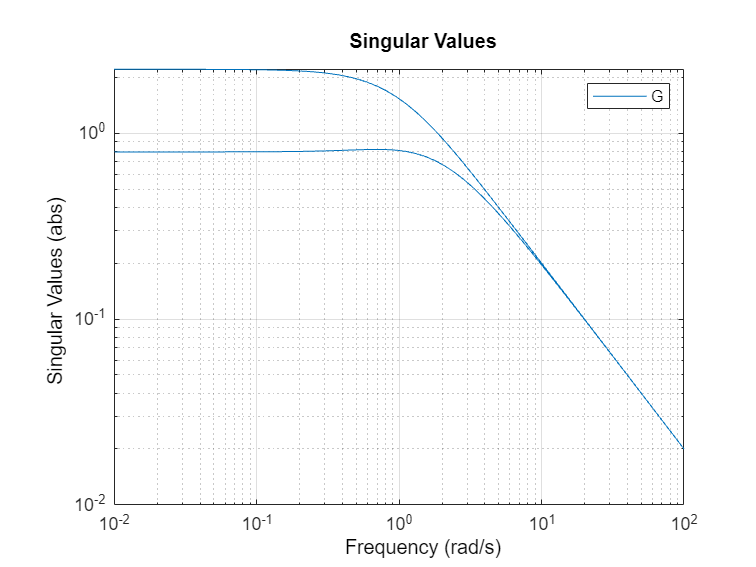


figure
h = sigmaplot(G);
setoptions(h,'MagUnits','abs');
legend()

b) 

    The tacking performance can be read from the max singular values of S, at 0.1 rad/s it is about 0.78

c) 

    The disturbance rejection can be read from the max singular values of T, at 10 rad/s it is about 0.04 (40x reduction)

d) 

    For multiplicative uncertainty the stability test with a $|\Delta | \leq 1$ and unit weighting is $||T||_{\infty}<1$. When the uncertainty is no longer unitary, the test becomes $||T||_{\infty}<\frac{1}{\gamma}$, where $|\Delta | \leq \gamma$. To destablize the system we set $\frac{1}{\gamma}$ to the max singular value of T, 0.7 @ 2 rad/s. $\gamma = 1.4$.

    For inverse multiplicative uncertainty the stability test with a $|\Delta | \leq 1$ and unit weighting is $||S||_{\infty}<1$. When the uncertainty is no longer unitary, the test becomes $||S||_{\infty}<\frac{1}{\gamma}$, where $|\Delta | \leq \gamma$. To destablize the system we set $\frac{1}{\gamma}$ to  the max singular value of S, 1.2 @ 3 rad/s. $\gamma = 0.833$.

## 3.

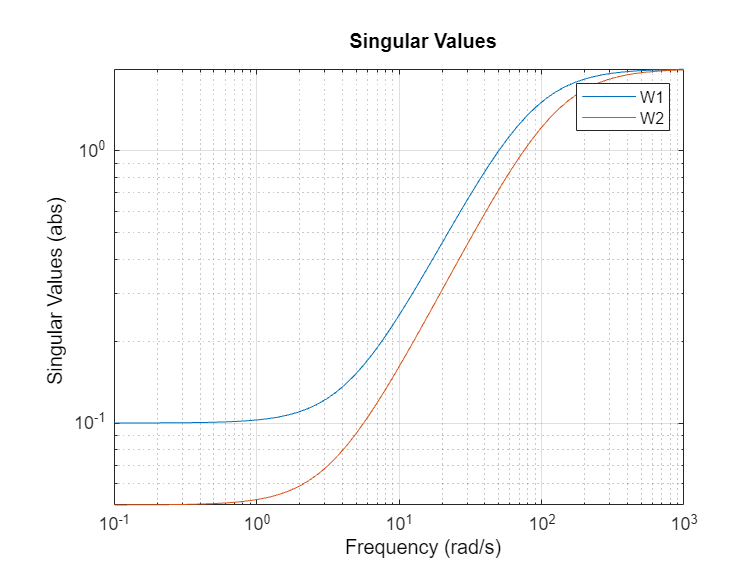

tau = 50;
s = tf('s');
l = tau*s + 1;
G = 1/l * [-87.8 1.4;
         -108.2 -1.4];
K = l/s * [-1.5e-3 0;
           0 -7.5e-2];

W1 = makeweight(0.1,50,2);
W2 = makeweight(0.05,75,2);

figure
h = sigmaplot(W1, W2);
setoptions(h,'MagUnits','abs');
legend("W1", "W2");

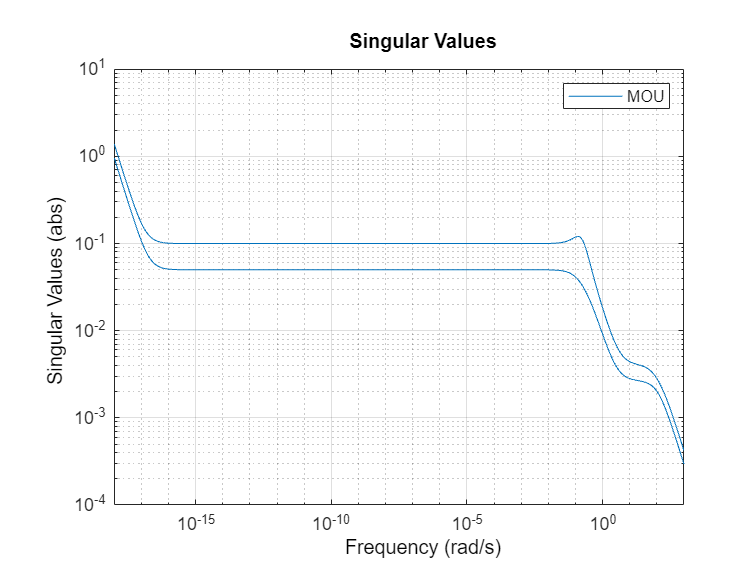

L = G*K;
S = 1 / (eye(2) + L);
T = L * S;
W = [W1 0; 0 W2];

figure 
h = sigmaplot(minreal(W * T));
setoptions(h,'MagUnits','abs');
legend("MOU")

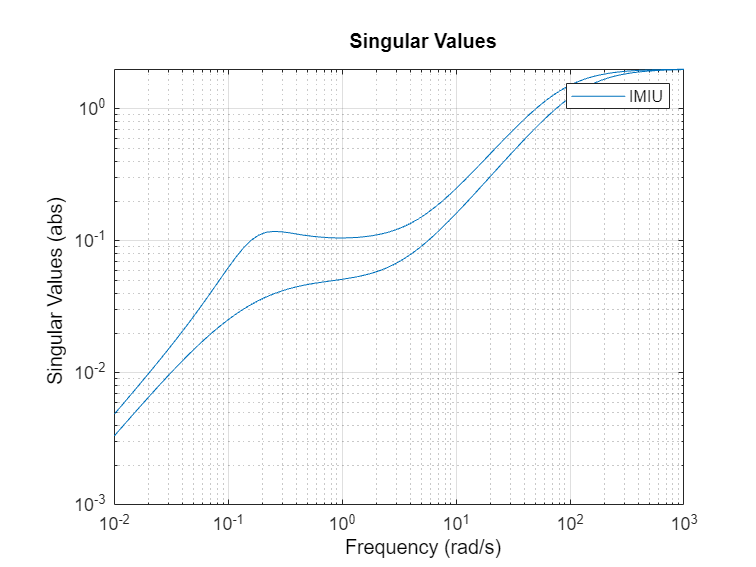


figure 
h = sigmaplot(minreal(W * S));
setoptions(h,'MagUnits','abs');
legend("IMIU");

The robust margin for MOU is about 2/3 and for IMIU it's 1/2.